# Birds at risk

Determine how many birds are at risk of collision with windturbine where and when.

## Load data

Load windfarm data which has been processed (`windfram_processing.mlx`)

load('data/windfarms_processed.mat')

Load the grid of the bird density estimation

load('../2018/data/Density_estimationMap','g');

Load flow estimation (density and speed)

load('../2018/data/Density_estimationMap','gd');
load('../2018/data/Flight_estimationMap','guv');

Load the ratio map of altiudinal distribution of the bird

load('./data/ratio');
%g_ratio = 0.05;

## Compute Bird at Risk

## Construct turbine sweep area map

[G,ID] = findgroups(tim.grid_id);
turbineSweptArea=nan(1,g.nlm);
turbineSweptArea(ID) = splitapply(@nansum,tim.turbine_sweptArea.*tim.Number_of_turbines,G);
turbineSweptAreaMap = nan(size(g.latlonmask));
turbineSweptAreaMap(g.latlonmask) = turbineSweptArea;

Display data

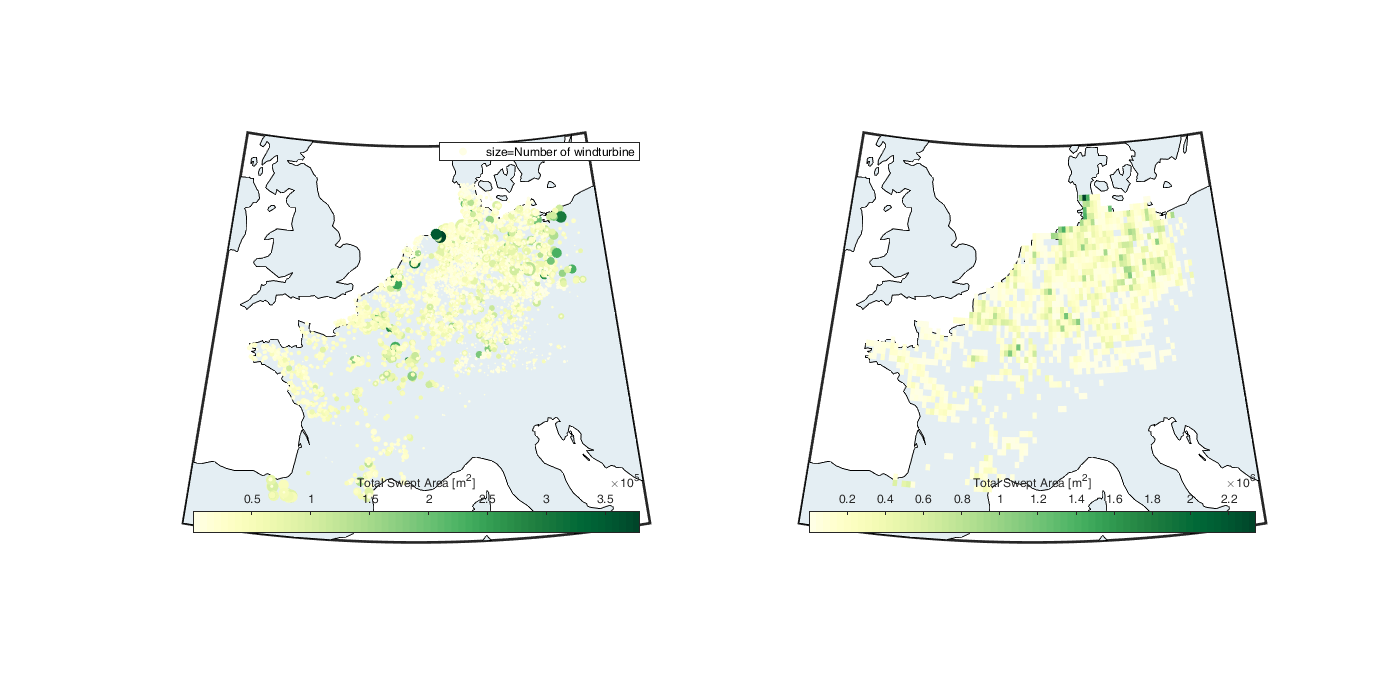

figure('position',[0 0 1400 700]); 
subplot(1,2,1); hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [228 238 243]./255);
tmp = scatterm(tim.Latitude,tim.Longitude,tim.Number_of_turbines*2,tim.Number_of_turbines.*tim.turbine_sweptArea,'filled','MarkerFaceAlpha',.2);
c=colorbar('south'); c.Label.String='Total Swept Area [m^2]';
legend(tmp,'size=Number of windturbine')
subplot(1,2,2); hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [228 238 243]./255);
surfm(g.lat,g.lon,turbineSweptAreaMap)
c=colorbar('south'); c.Label.String='Total Swept Area [m^2]';
colormap(brewermap([],'YlGn'))

## Bird Flow at Wind turbine height

Compute the bird flow [bird/m^2/hr] as


$$\rho \cdot r_{\textrm{wt}} \cdot \frac{1}{h}\cdot v$$


- $\rho$ : bird density [bird/km^2]

- $r_{\textrm{wt}}$: ratio of bird density (in bird/km^2) at windturbine elevation [-]

- $h$: height assumed when computing the ratio. [m]

- $v=\sqrt{v_u^2 +v_u^{2\;} }$: bird speed [m/s]

birdFlow_tmp = nan(g.nlat,g.nlon,g.nt);
birdFlow_tmp(repmat(g.latlonmask,1,1,g.nt)) = gd.dens_est * 1e-6 .* g_ratio / (windturbine_maxheight-windturbine_minheight)  .* sqrt(guv.u_est.^2 + guv.v_est.^2)*60*60; 

UNIT check: bird/km^2 * km^2/m^2 * - * 1/m * m/s * s/hr -> bird/m^2 * 1/m * m/hr -> bird/m^2/hr

Convert time resolution of birdflow to match energy map. Average for the previous hour as wind is also the average over the previous hour.

[~,Locb]=ismember(dateshift(g.time,'end','hour'),time);
birdFlow = nan(g.nlat,g.nlon,numel(time));
for i=1:numel(time)
    birdFlow(:,:,i) = nanmean(birdFlow_tmp(:,:,Locb==i),3);
end

## Bird at Risk

Compute the bird at risk as bird flow [bird/m^2/hr] x total swept area [m^2]

birdAtRisk = birdFlow .* turbineSweptAreaMap;

Figure

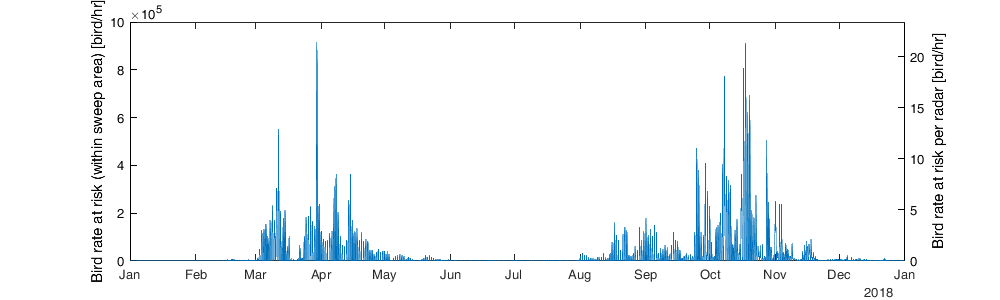

figure('position',[0 0 1000 300]); 
plot(time,reshape(nansum(nansum(birdAtRisk,1),2),1,[]));
ylim([0 1e6]);ylabel('Bird rate at risk (within sweep area) [bird/hr]')
yyaxis 'right'
ax = gca; ax.YAxis(2).Color = 'k';
ylim([0 1e6]/nansum(tim.Number_of_turbines)); ylabel('Bird rate at risk per radar [bird/hr]')

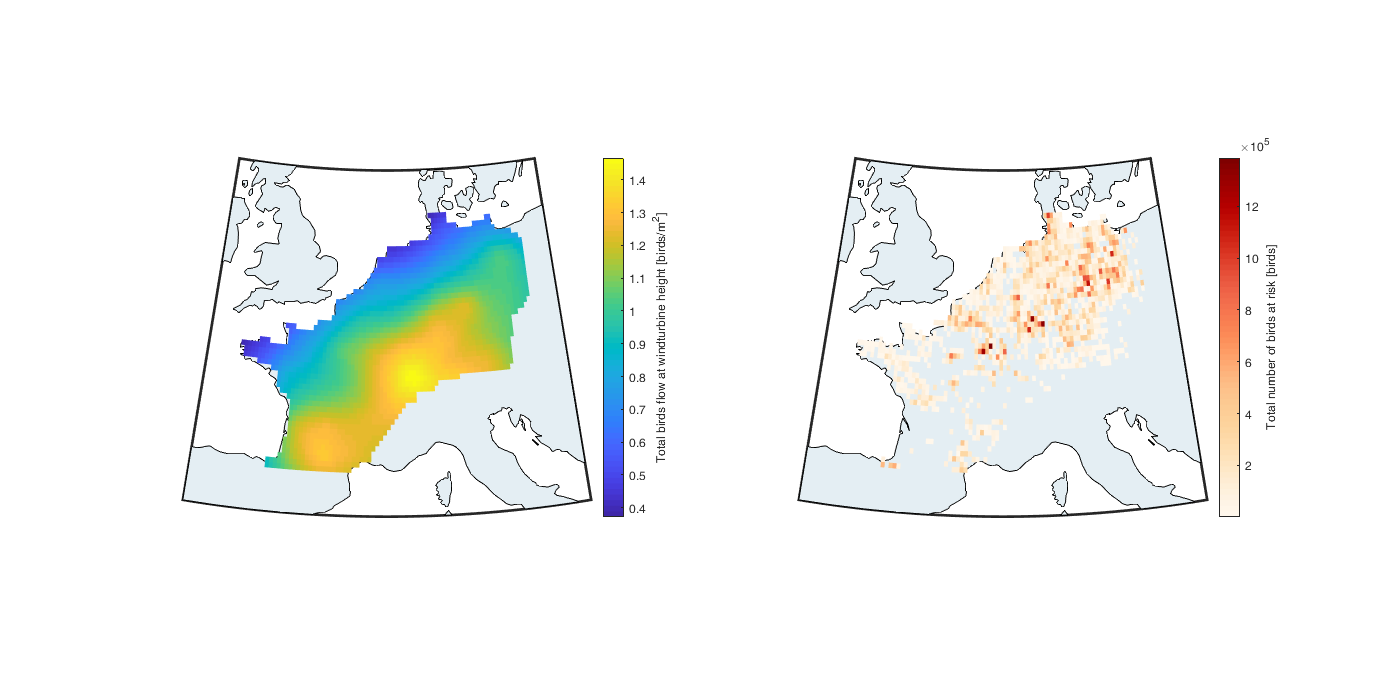

figure('position',[0 0 1400 700]); 
subplot(1,2,1); hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [228 238 243]./255);
tmp = nansum(birdFlow,3); % birds/hr -> birds (resolution of 1hr)
tmp(tmp==0)=nan;
surfm(g.lat,g.lon,tmp)
c=colorbar(); c.Label.String='Total birds flow at windturbine height [birds/m^2]';
ax=subplot(1,2,2);hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [228 238 243]./255);
tmp = nansum(birdAtRisk,3); % /4 to convert birds/hr -> birds (resolution of 15min)
tmp(tmp==0)=nan;
surfm(g.lat,g.lon,tmp)
c=colorbar(); c.Label.String='Total number of birds at risk [birds]';
colormap(ax,brewermap([],'OrRd'))

## Simulated Bird density

Run on UNIL server

% rar = nan(g.nt,500);

prepare the birdrisk template (just need to multiply by density

% birdAtRisk_t = nan(g.nlat,g.nlon,g.nt);
% birdAtRisk_t(repmat(g.latlonmask,1,1,g.nt)) = turbineSweptArea' * 1e-6 .* g_ratio / (windturbine_maxheight-windturbine_minheight)  .* sqrt(guv.u_estim.^2 + guv.v_estim.^2)*60*60; 

Loop through all files

% for ii=1:5
%     load(['D:\Guests\rafnuss_at_gmail_com\tmp_BMM2018\Density_simulationMap_reassemble_' num2str(ii)]);
%     for i_real = 1:size(real_dens,4)
%         rar(:, (ii-1)*100+i_real) = reshape(nansum(nansum(birdAtRisk_t .* real_dens(:,:,:,i_real),1),2),1,[]);
%     end
% end

Save

% save('data/BirdAtRisk_sim','rar')

Load

load('data/BirdAtRisk_sim')

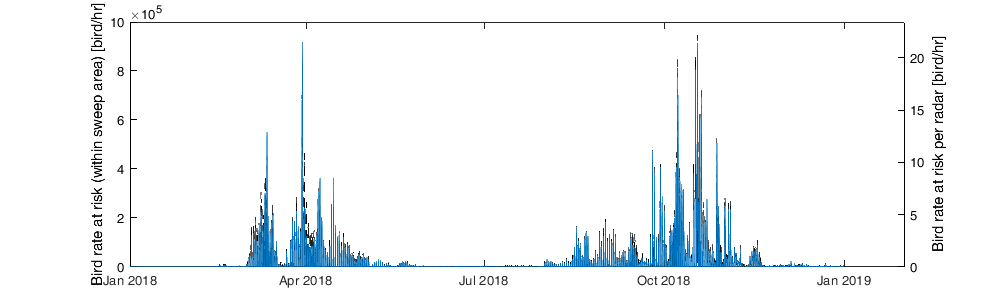

figure('position',[0 0 1000 300]);  hold on;
plot(g.time,nanmean(rar,2),'k')
plot(g.time,quantile(rar,.1,2),'--k')
plot(g.time,quantile(rar,.9,2),'--k')
plot(time,reshape(nansum(nansum(birdAtRisk,1),2),1,[]),'LineWidth',0.1);

ylim([0 1e6]);ylabel('Bird rate at risk (within sweep area) [bird/hr]')
yyaxis 'right'
ax = gca; ax.YAxis(2).Color = 'k'; box on
ylim([0 1e6]/nansum(tim.Number_of_turbines)); ylabel('Bird rate at risk per radar [bird/hr]')

## Compute Power Production

Put the power on a grid

tmp=nan(g.nlm,numel(time));
for i_ll=1:g.nlm
    id = tim.grid_id==i_ll;
    tmp(i_ll,:) = nansum(power(id,:),1);
    % tmp(i_ll,:) = nansum(max(tim.powerCurve(id,:),[],2).*tim.Number_of_turbines(id));
end
energy=nan(g.nlat,g.nlon,numel(time));
energy(repmat(g.latlonmask,1,1,numel(time))) = tmp*1000*60*60; % convert kW -> J
% plot(max(power'),tim.turbine_capacity.*tim.Number_of_turbines,'.k')

Put turbine Capacity and Number of turbine on a map

[G,ID] = findgroups(tim.grid_id);
tmp=nan(1,g.nlm);
tmp(ID) = splitapply(@nansum,tim.turbine_capacity.*tim.Number_of_turbines,G);
capacityMap = nan(size(g.latlonmask));
capacityMap(g.latlonmask) = tmp;
% tmp=nan(1,g.nlm);
% tmp(ID) = splitapply(@nansum,tim.Number_of_turbines,G);
% turbineNumberMap = nan(size(g.latlonmask));
% turbineNumberMap(g.latlonmask) = tmp;

Display data

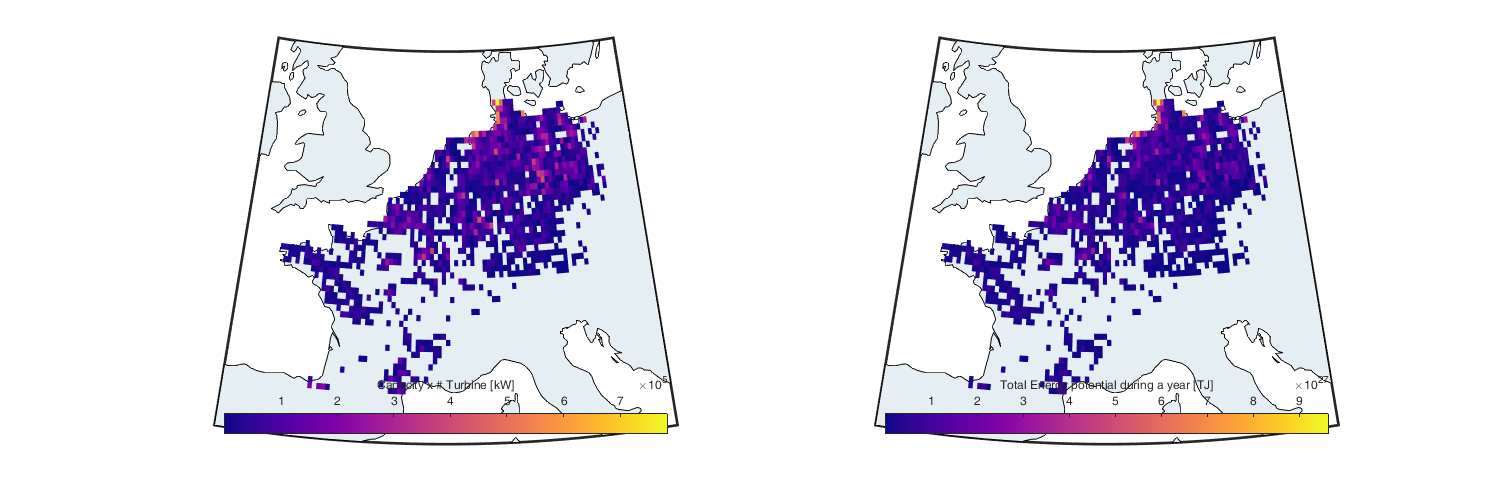

figure('position',[0 0 1500 500]); 
subplot(1,2,1); hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [228 238 243]./255);
surfm(g.lat,g.lon,capacityMap)
c=colorbar('south'); c.Label.String='Capacity x # Turbine [kW]';
subplot(1,2,2); hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [228 238 243]./255);
tmp = nansum(energy,3); % 
tmp(tmp==0)=nan; 
surfm(g.lat,g.lon,tmp/1e-12)
%scatterm(tim.Latitude,tim.Longitude,'.k');
c=colorbar('south'); c.Label.String='Total Energy potential during a year [TJ]';
colormap(plasma)

## Combine Bird at Risk and Energy

% birdAtRiskPerEnergy = birdAtRisk./energy;

Plot

figure('position',[0 0 1500 500]); 
ax1=subplot(1,3,1);hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [228 238 243]./255);
tmp = nansum(birdAtRisk,3); % /4 to convert birds/hr -> birds (resolution of 15min)
tmp(tmp==0)=nan;
surfm(g.lat,g.lon,tmp)
c=colorbar('south'); title('Total number of birds at risk [birds]');
colormap(ax1,brewermap([],'OrRd'))

ax2=subplot(1,3,2); hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [228 238 243]./255);
tmp2 = nansum(energy,3); % 
tmp2(tmp2==0)=nan; 
surfm(g.lat,g.lon,tmp2/1e12)
%scatterm(tim.Latitude,tim.Longitude,'.k');
c=colorbar('south'); title('Total Energy potential during a year [TJ]');
colormap(ax2,plasma)

ax3=subplot(1,3,3); hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [228 238 243]./255);
surfm(g.lat,g.lon,tmp2./tmp)
%scatterm(tim.Latitude,tim.Longitude,'.k');
c=colorbar('south'); title('Energy per Bird at Risk [TJ/birds]');
colormap(ax3,viridis)

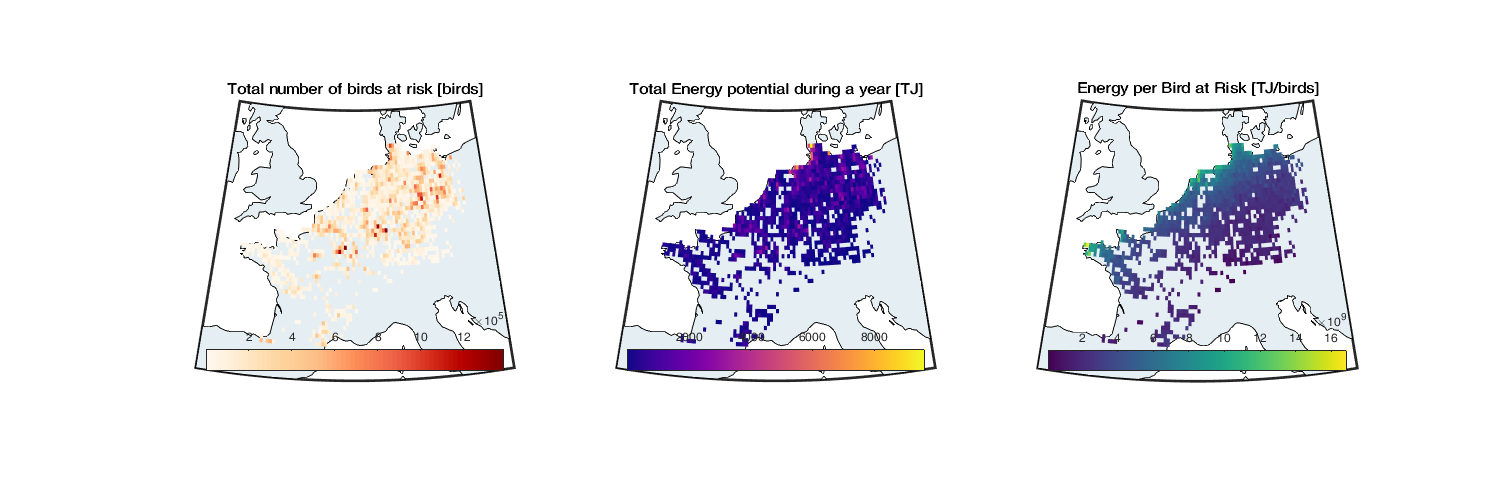

figure('position',[0 0 1400 500]); 
plot(time,reshape(nansum(nansum(energy,1),2),1,[]))

ylabel('Energy Potential [J]')
yyaxis right
plot(time,reshape(nansum(nansum(birdAtRisk,1),2),1,[]))
ylabel('Birds at Risk [birds/hr]')
ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';

## Save

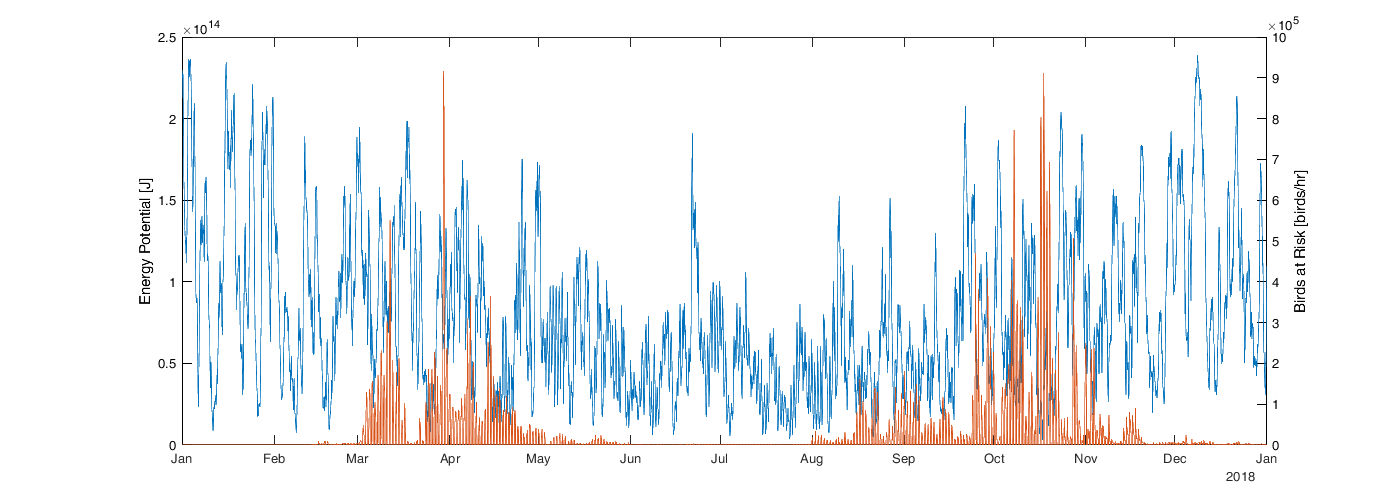

save('data/birdAtRisk.mat','birdAtRisk','energy');